# Plant

## First section

Gs=tf([0.129],[0.00113 0.0844 0])

Gs =
 
          0.129
  ----------------------
  0.00113 s^2 + 0.0844 s
 
Continuous-time transfer function.



T=feedback(Gs,[1])

T =
 
              0.129
  ------------------------------
  0.00113 s^2 + 0.0844 s + 0.129
 
Continuous-time transfer function.



## Second Section

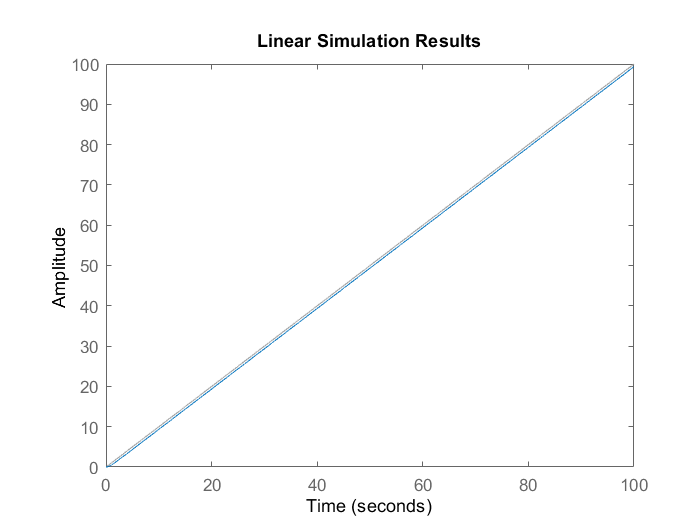

lsim(T,[0:0.01:100],[0:0.01:100])

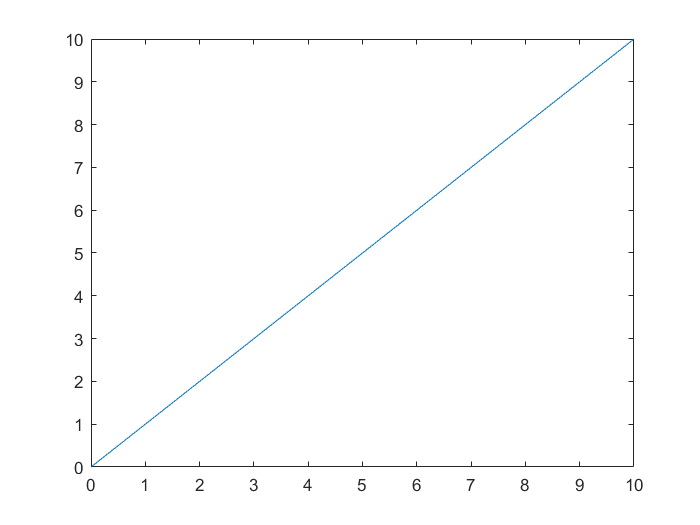

u=[0:0.01:10];
t=[0:0.01:10];
plot(t,u)

# Contorller

Gc=tf([1 0.1],[1 0])

Gc =
 
  s + 0.1
  -------
     s
 
Continuous-time transfer function.



TFol=series(Gc,Gs)

TFol =
 
      0.129 s + 0.0129
  ------------------------
  0.00113 s^3 + 0.0844 s^2
 
Continuous-time transfer function.



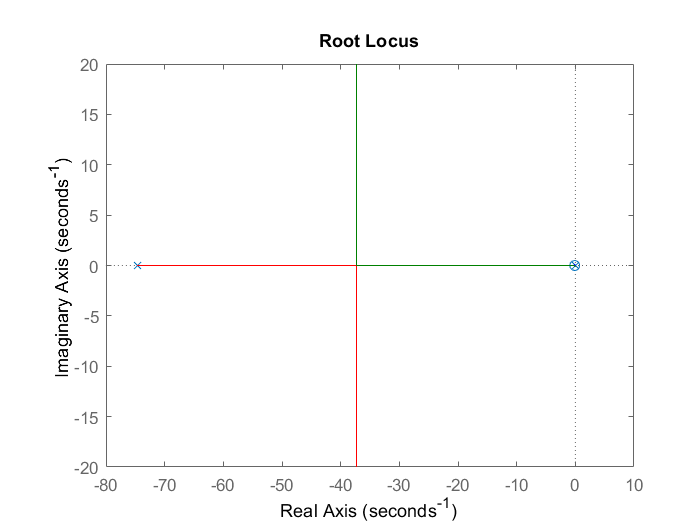

rlocus(TFol)

# Error

numtf=[0 0 2.58 0.258];
dentf=[0.00113 0.0844 0 0];
denE=dentf+numtf;
numE=dentf;
Etf=tf(numE,denE)


Etf =
 
          0.00113 s^3 + 0.0844 s^2
  -----------------------------------------
  0.00113 s^3 + 0.0844 s^2 + 2.58 s + 0.258
 
Continuous-time transfer function.



stepinfo(Etf)

ans =         RiseTime: 0.0500
    SettlingTime: 0.1189
     SettlingMin: -0.0228
     SettlingMax: 0.0918
       Overshoot: 9.0072e+17
      Undershoot: 2.0527e+16
            Peak: 1
        PeakTime: 0


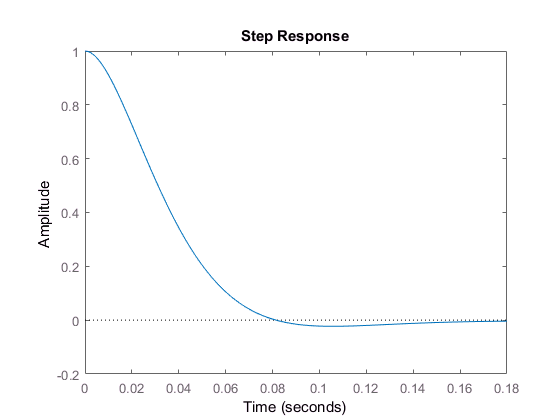

step(Etf)

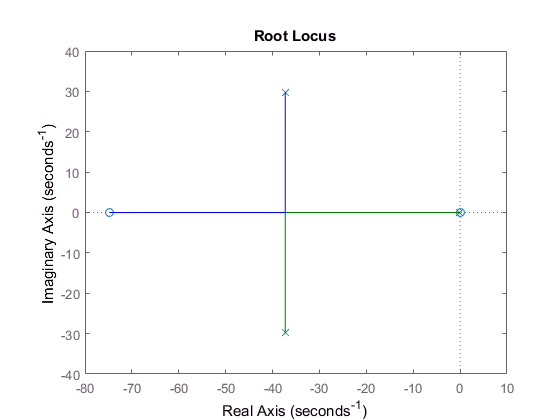

rlocus(Etf)

rad2deg(0.6)

ans = 34.3775